# MATLAB Visualizations

## `plot`

- Most common plotting tool in MATLAB

- Basic syntax involves only two arrays of numbers *X *and *Y*

-  *h *can be used to refer to the plot in later code

- `LineSpec` specifies line, marker type, and colors

- `Name,Value `pairs are another way to specify line and marker properties

X = sort(rand(12,1));
Y = sort(rand(12,1));
h = plot(X,Y)
h.XData = Y

MATLAB specifiers include

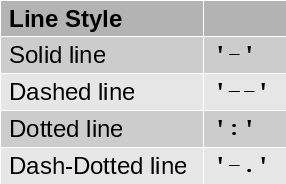

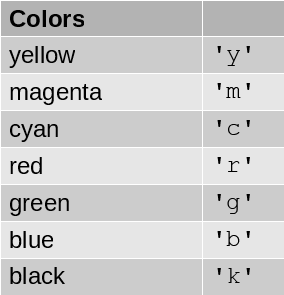

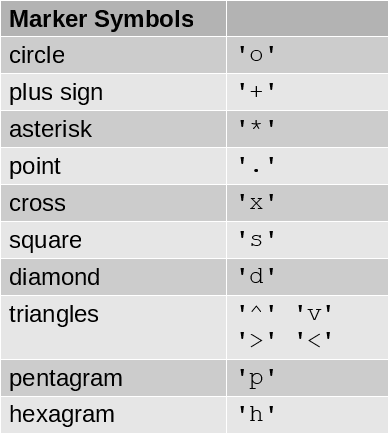

plot(gca,X,2*Y,'r--^')
h = plot(X,Y, 'Color', 'b', 'LineWidth', 1, 'Marker','^','LineStyle','-.', 'MarkerEdgeColor','m')

## Related Functions to `plot`

There are commands to include titles, axes labels, and other modifications.

clf % clears the current figure
x = linspace(0,10); % linspace creates an array in the range of 0 to 10
y = sin(3*x);
yyaxis left; % sets next plot statement to use left side y axis
plot(x,y);
xlabel('horizontal position (m)');
ylabel('vertical position (m)');

z = sin(3*x).*exp(0.5*x);
yyaxis right; % sets next plot statement to use right y axis
plot(x,z)
ylabel('alterative position');
ylim([-150 150])
clf % clears current figure window
x = 1:10:100;
y = [20 30 45 40 60 65 80 75 95 90];
err = 8*rand(size(y));
errorbar(x,y,err) % plots with errorbars

## Scatterplots

MATLAB produces scatterplots using the function` scatter`. `scatter `syntax looks like

`scatter``(X,Y)`

`scatter(``X,Y``,sz``)`

`scatter(``X,Y``,sz,``c``)`

`scatter(___,'filled')`

`scatter``(___,’<``markertype``>')`

`scatter(___,'``Name','Value``')`

`scatter(ax,___)`

`scatter3(___)`

- creates a 2-D scatter plot

- defines the area of the points (scalar or vector)

- defines the color of the plot (scalar or vector)

- `'filled' `specifies whether markers are filled

- `'markertype``'`, `'Name'`, and `'Value'`follows the same conventions as the function plot

- `scatter3 `creates a 3-D scatter plot  

theta = linspace(0,1,500); % 500 points between 0 and 1
x = exp(theta).*sin(100*theta);
y = exp(theta).*cos(100*theta);
s = scatter(x,y);
xlabel('x');
ylabel('y');
scatter(x,y,'filled','d'); % defines filled diamonds
sz = linspace(1,100,500); % array to change the size of every point
scatter(x,y,sz)
X =54
Y =30
plot(rand(14,1)*Y, rand(14,1)*Y)

## Contour Plots

MATLAB produces contour plots using `contour`:

`contour(Z)`

`contour(``Z,n``)`

`contour(X,Y,Z)`

`contour(``X,Y,Z,n``)`

`contour(___,'``LineSpec``')`

`contour(___,'``Name','Value``')`

`contour(ax,___)`

`[``C,h``] = contour(___)`

`[``C,h``] = contour3(___)`

- creates a contour plot of the matrix *Z, *where columns correspond to *x*-coordinates and rows to *y*-coordinates

- *n *specifies number of contour lines (isolines)

- *X *and *Y (*same size as *Z) *determine the x- and y-coordinates in the plot

- *C *contains the contour matrix

- *h *contains the plot object (refer to this to change properties of the contour plot)

Z = rand(5,5) % random matrix of values
contour(Z) % contour plot the random values above
[X,Y,Z]=peaks; %peaks is a built-in functions that produces the plot below. type peaks into the command line and see what happens
contour(X,Y,Z,10,'--')
contour(X,Y,Z,10,'Showtext','on')
contour(X,Y,Z,30,'Showtext','off')

## Histograms

`histogram(X)`

`histogram(``X,nbins``)`

`histogram(``X,edges``)`

`histogram(___,'``Name','Value``')`

`histogram``(ax,___)`

`h = histogram(___)`

- creates histogram of the vector *X*

- specify number of bins (`nbins`) or the edges of the bins (`edges`)

- `'Name'` / `'Value' `pairs allow you to change the bin width, color, outline color, etc.

- histogram returns an object `h` for future modification reference

% Role of the dice
x = randi([1,6],500,1); % returns 500 random numbers between 1 and 6
y = randi([1,6],500,1);
histogram(x+y);
histogram(x+y,4); % changes number of bins
edges = [1.5:12.5];
histogram(x+y,edges);

You can even make categorical histograms

A = [0 0 1 1 1 0 0 0 0 NaN NaN 1 0 0 0 1 0 1 0 1 0 0 0 1 1 1 1];
C = categorical(A,[1 0 NaN],{'yes','no','undecided'})
h = histogram(C,'BarWidth',0.5);

## Displaying Vectors

You have a variety of options when displaying vectors in MATLAB. 

**quiver **- 

- creates a vector field

- plots a vector <u,v> at every point <x,y>

- scale the vectors to any size

- specify display options using `Linespec` or `Name|Value` pairs

[x,y] = meshgrid(0:0.2:2,0:0.2:2); % What does meshgrid do?
u = cos(x).*y;
v = sin(x).*y;

quiver(x,y,u,v)

**feather**

- creates vectors emanating from equally spaced points along a horizontal axis

- express the vector components U and V relative to the origin of the respective vector

- Z is a complex number, using it is equivalent to `feather(real(Z),imag(Z)) `

theta = -pi/2:pi/16:pi/2;
r = 2*ones(size(theta));
[u,v] = pol2cart(theta,r);
feather(u,v)

**compass**

operates just as feather but the vectors originate at the origin of a compass plot

n = -4:4;
Z = exp(2*pi*i./n);
compass(Z)

## Animated Plots

- To see lines drawn by MATLAB, use the function `animatedline`

- it has the same syntax as plot

- Use `addpoints` to add points as the program process

- `pause(n)`halts the program execution for n seconds if you desire a slower animation.

clf
h = animatedline;
axis([0,4*pi,-1,1])

x = linspace(0,4*pi,1000);
y = sin(x);
for k = 1:length(x)
    addpoints(h,x(k),y(k));
    drawnow
end
